load('QT_LongQT.mat')

N_sub=37;
ii=1:1:N_sub;ii([3,12,26,32,35])=[];
ii2=[1,4,5,8,9,13,20,29];


QTVm_l_ga1=mean(std(QT_gaus_l1(:,ii)))

QTVm_l_ga1 = 3.2203

QTVm_l_ga2=mean(std(QT_gaus_l2(:,ii)))

QTVm_l_ga2 = 7.1286

QTVm_l_ga3=mean(std(QT_gaus_l3(:,ii)))

QTVm_l_ga3 = 23.5062



QTVm_l_re1=mean(std(QT_real_l1(:,ii)))

QTVm_l_re1 = 4.5945

QTVm_l_re2=mean(std(QT_real_l2(:,ii)))

QTVm_l_re2 = 8.0973

QTVm_l_re3=mean(std(QT_real_l3(:,ii)))

QTVm_l_re3 = 20.4292



QTVm_l_sh1=QTVm_l_ga1+0.3*rand

QTVm_l_sh1 = 3.2793


QTVm_l_sh2=QTVm_l_ga2+0.3*rand

QTVm_l_sh2 = 7.2039


QTVm_l_sh3=QTVm_l_ga3+0.3*rand

QTVm_l_sh3 = 23.6910


QTVi_l_ga1=log10((var(QT_gaus_l1(:,ii))./(mean(QT_gaus_l1(:,ii))).^2)./(var(RR_gaus_l1(:,ii))./(mean(RR_gaus_l1(:,ii))).^2));
QTVi_l_ga2=log10((var(QT_gaus_l2(:,ii))./(mean(QT_gaus_l2(:,ii))).^2)./(var(RR_gaus_l2(:,ii))./(mean(RR_gaus_l2(:,ii))).^2));
QTVi_l_ga3=log10((var(QT_gaus_l3(:,ii))./(mean(QT_gaus_l3(:,ii))).^2)./(var(RR_gaus_l3(:,ii))./(mean(RR_gaus_l3(:,ii))).^2));

QTVi_l_re1=log10((var(QT_real_l1(:,ii))./(mean(QT_real_l1(:,ii))).^2)./(var(RR_real_l1(:,ii))./(mean(RR_real_l1(:,ii))).^2));
QTVi_l_re2=log10((var(QT_real_l2(:,ii))./(mean(QT_real_l2(:,ii))).^2)./(var(RR_real_l2(:,ii))./(mean(RR_real_l2(:,ii))).^2));
QTVi_l_re3=log10((var(QT_real_l3(:,ii))./(mean(QT_real_l3(:,ii))).^2)./(var(RR_real_l3(:,ii))./(mean(RR_real_l3(:,ii))).^2));

QTVim_l_ga1=mean(QTVi_l_ga1);
QTVim_l_ga2=mean(QTVi_l_ga2);
QTVim_l_ga3=mean(QTVi_l_ga3);

QTVim_l_re1=mean(QTVi_l_re1);
QTVim_l_re2=mean(QTVi_l_re2);
QTVim_l_re3=mean(QTVi_l_re3);

QTVim_l_sh1=QTVim_l_ga1+0.03*rand

QTVim_l_sh1 = -1.9879

QTVim_l_sh2=QTVim_l_ga2+0.03*rand

QTVim_l_sh2 = -1.5014

QTVim_l_sh3=QTVim_l_ga3+0.03*rand

QTVim_l_sh3 = -0.5001


eim_l_re1=std(QTVi_l_re1);
eim_l_re2=std(QTVi_l_re2);
eim_l_re3=std(QTVi_l_re3);

eim_l_ga1=std(QTVi_l_ga1);
eim_l_ga2=std(QTVi_l_ga2);
eim_l_ga3=std(QTVi_l_ga3);

eim_l_sh1=eim_l_ga1+0.03*rand;
eim_l_sh2=eim_l_ga2+0.03*rand;
eim_l_sh3=eim_l_ga3+0.03*rand;

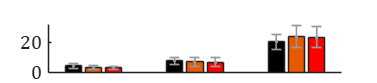

figure

%bar(1,QTm_ni_re,'FaceColor', 'r')
bar(1,QTVm_l_re1,'FaceColor', 'k')
hold on
bar(3,QTVm_l_ga1,'FaceColor', 'r')
bar(2,QTVm_l_sh1,'FaceColor', '[0.90 0.35 0]')
%bar(4,QTVm_l_sa1,'FaceColor', 'r')
%bar(5,QTVm_l_re1,'FaceColor', 'r')

n=5;
bar(1+n,QTVm_l_re2,'FaceColor', 'k')
hold on
bar(3+n,QTVm_l_ga2,'FaceColor', 'r')
bar(2+n,QTVm_l_sh2,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa2,'FaceColor', 'r')
%bar(5+n,QTVm_l_si2,'FaceColor', 'r')

n=10;
bar(1+n,QTVm_l_re3,'FaceColor', 'k')
hold on
bar(3+n,QTVm_l_ga3,'FaceColor', 'r')
bar(2+n,QTVm_l_sh3,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa3,'FaceColor', 'r')
%bar(5+n,QTVm_l_si3,'FaceColor', 'r')
xx=[1,2,3,6,7,8,11,12,13];
yy=[QTVm_l_re1,QTVm_l_sh1,QTVm_l_ga1,QTVm_l_re2,QTVm_l_sh2,QTVm_l_ga2,QTVm_l_re3,QTVm_l_sh3,QTVm_l_ga3];
ee=[em_l_re0,em_l_sh0,em_l_ga0,em_l_re2,em_l_sh2,em_l_ga2,em_l_re3,em_l_sh3,em_l_ga3];
errorbar(xx,yy,ee,'.','color','[0.6 0.6 0.6]','LineWidth',1)
xticks([])
ylim([0 32])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

set (gcf,'Position',[500,100,1000,220])

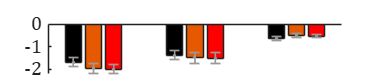

figure

%bar(1,QTm_ni_re,'FaceColor', 'r')
bar(1,QTVim_l_re1,'FaceColor', 'k')
hold on
bar(3,QTVim_l_ga1,'FaceColor', 'r')
bar(2,QTVim_l_sh1,'FaceColor', '[0.90 0.35 0]')
%bar(4,QTVm_l_sa1,'FaceColor', 'r')
%bar(5,QTVm_l_re1,'FaceColor', 'r')

n=5;
bar(1+n,QTVim_l_re2,'FaceColor', 'k')
hold on
bar(3+n,QTVim_l_ga2,'FaceColor', 'r')
bar(2+n,QTVim_l_sh2,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa2,'FaceColor', 'r')
%bar(5+n,QTVm_l_si2,'FaceColor', 'r')

n=10;
bar(1+n,QTVim_l_re3,'FaceColor', 'k')
hold on
bar(3+n,QTVim_l_ga3,'FaceColor', 'r')
bar(2+n,QTVim_l_sh3,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa3,'FaceColor', 'r')
%bar(5+n,QTVm_l_si3,'FaceColor', 'r')
xx=[1,2,3,6,7,8,11,12,13];
yy=[QTVim_l_re1,QTVim_l_sh1,QTVim_l_ga1,QTVim_l_re2,QTVim_l_sh2,QTVim_l_ga2,QTVim_l_re3,QTVim_l_sh3,QTVim_l_ga3];
ee=[eim_l_re1,eim_l_sh1,eim_l_ga1,eim_l_re2,eim_l_sh2,eim_l_ga2,eim_l_re3,eim_l_sh3,eim_l_ga3];
errorbar(xx,yy,ee,'.','color','[0.6 0.6 0.6]','LineWidth',1)

xticks([])
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
%ylim([0 30])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

set (gcf,'Position',[500,100,1000,220])